Reading the data from the source and converting the data into array

data=readtable("male_female.xlsx")

data = 12×3 table
    year    male    female
    ____    ____    ______

    2008     0.1       1  
    2009     0.2     0.3  
    2010     1.2     0.5  
    2011     2.2     0.5  
    2012     3.2     1.5  
    2013     4.2     2.5  
    2014     5.2     3.5  
    2015     6.2     4.5  
    2016     7.2     5.5  
    2017     8.2     6.5  
    2018     9.2     7.5  
    2019    10.2     8.5  


data=table2array(data)

data = 	1.0e+03 *

    2.0080    0.0001    0.0010
    2.0090    0.0002    0.0003
    2.0100    0.0012    0.0005
    2.0110    0.0022    0.0005
    2.0120    0.0032    0.0015
    2.0130    0.0042    0.0025
    2.0140    0.0052    0.0035
    2.0150    0.0062    0.0045
    2.0160    0.0072    0.0055
    2.0170    0.0082    0.0065


Plot the graph for the women in the curve

women=data(:,3)

women =     1.0000
    0.3000
    0.5000
    0.5000
    1.5000
    2.5000
    3.5000
    4.5000
    5.5000
    6.5000


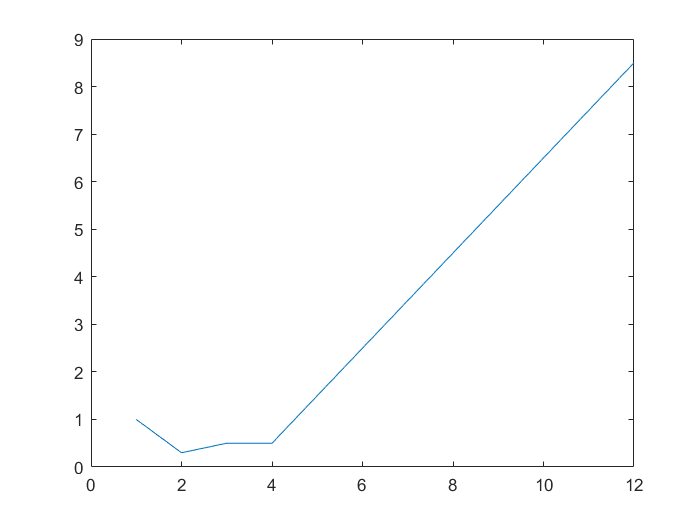

figure
plot(women)

year on the x axis

years=data(:,1)

years =         2008
        2009
        2010
        2011
        2012
        2013
        2014
        2015
        2016
        2017


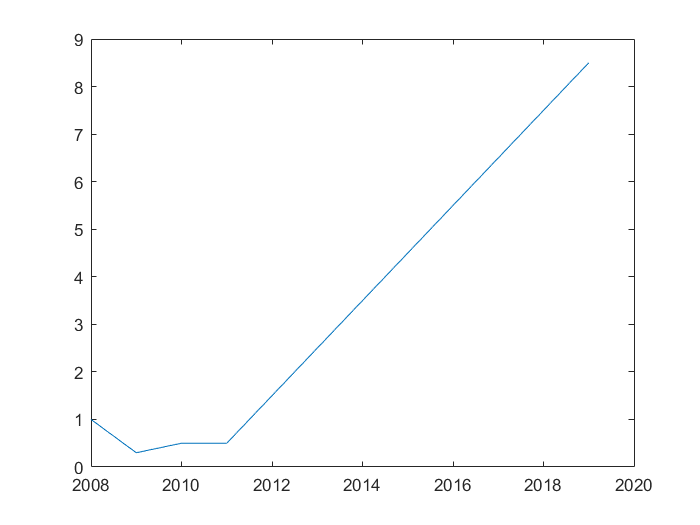

figure
plot(years,women)

men on the plot

men=data(:,2)

men =     0.1000
    0.2000
    1.2000
    2.2000
    3.2000
    4.2000
    5.2000
    6.2000
    7.2000
    8.2000


figure
hold on
plotW=plot(years,women)

plotW =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019]
              YData: [1 0.3000 0.5000 0.5000 1.5000 2.5000 3.5000 4.5000 5.5000 6.5000 7.5000 8.5000]
              ZData: [1×0 double]

  Show all properties


plotM=plot(years,men)

plotM =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [2008 2009 2010 2011 2012 2013 2014 2015 2016 2017 2018 2019]
              YData: [0.1000 0.2000 1.2000 2.2000 3.2000 4.2000 5.2000 6.2000 7.2000 8.2000 9.2000 10.2000]
              ZData: [1×0 double]

  Show all properties


enhancing the  beauty of the plot

title('Unemployment rate of Nepal for both MEn ')
xlabel("number of years in the x axis")
ylabel("number of men and women rate in %")
legendme=legend('men','women')

legendme =   Legend (men, women) with properties:

         String: {'men'  'women'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.7256 0.8134 0.1611 0.0869]
          Units: 'normalized'

  Show all properties


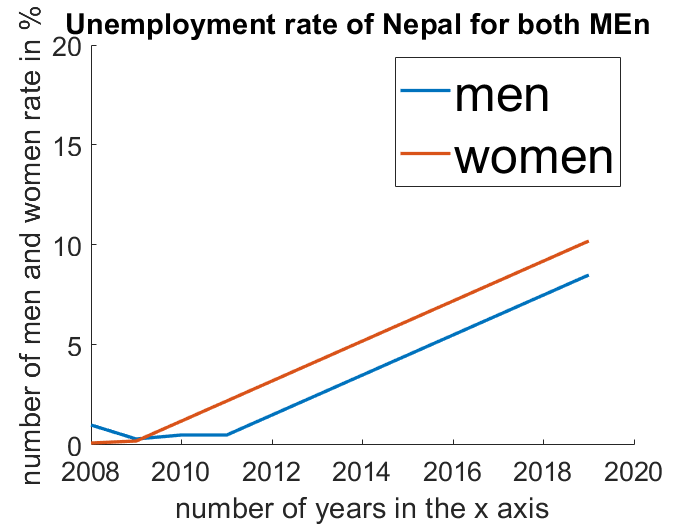

xlim([2008,2020])
ylim([0,20])
set(gca,'fontsize',16)
set([plotM,plotW],'linewidth',2)
set(legendme,'fontsize',30)